**Exemplos**

**Diferenças Entre Elementos de um Vetor **

Cria um vetor e calcula as diferenças entre os elementos.

X = [1 1 2 3 5 8 13 21];
Y = diff(X)

Y =      0     1     1     2     3     5     8


**Diferenças Entre Linhas de uma Matriz **

Cria uma matriz 3x3 e calcula a primeira diferença entre as linhas.

X = [1 1 1; 5 5 5; 25 25 25];
Y = diff(X)

Y =      4     4     4
    20    20    20


**Diferenças Múltiplas **

Cria um vetor e calcula a diferença de segunda ordem entre os elementos.

X = [0 5 15 30 50 75 105];
Y = diff(X,2)

Y =      5     5     5     5     5


**Diferenças Entre Colunas de uma Matriz** 

Cria uma matriz 3x3 e calcula a diferença de primeira ordem entre as colunas.

X = [1 3 5;7 11 13;17 19 23];
Y = diff(X,1,2)

Y =      2     2
     4     2
     2     4


**Aproximação de Derivadas com diff **

Usa a função diff para aproximar derivadas parciais com a sintaxe Y = diff(f)/h, onde f é um vetor de valores da função avaliados sobre algum domínio X, e h é um tamanho de passo apropriado.

Por exemplo, a primeira derivada de sin(x) em relação a x é cos(x), e a segunda derivada em relação a x é -sin(x). Podes usar diff para aproximar estas derivadas.

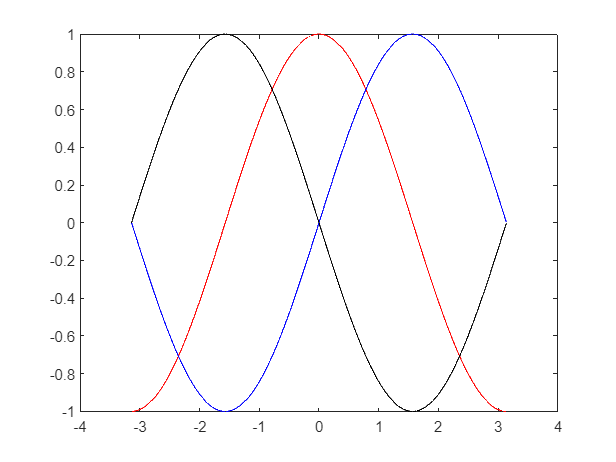

h = 0.001;       % passo
X = -pi:h:pi;    % domínio
f = sin(X);      % função
Y = diff(f)/h;   % 1ª derivada
Z = diff(Y)/h;   % 2ª derivada
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k')

Neste gráfico, a linha azul corresponde à função original, sin. A linha vermelha corresponde à primeira derivada calculada, cos, e a linha preta corresponde à segunda derivada calculada, -sin.

**Diferenças Entre Valores de Data e Hora **

Cria uma sequência de valores de data e hora igualmente espaçados e encontra as diferenças de tempo entre eles.

t1 = datetime('now');
t2 = t1 + minutes(5);
t = t1:minutes(1.5):t2

t = 1×4 datetime array
   27-May-2024 11:11:11   27-May-2024 11:12:41   27-May-2024 11:14:11   27-May-2024 11:15:41


dt = diff(t)

dt = 1×3 duration array
   00:01:30   00:01:30   00:01:30
